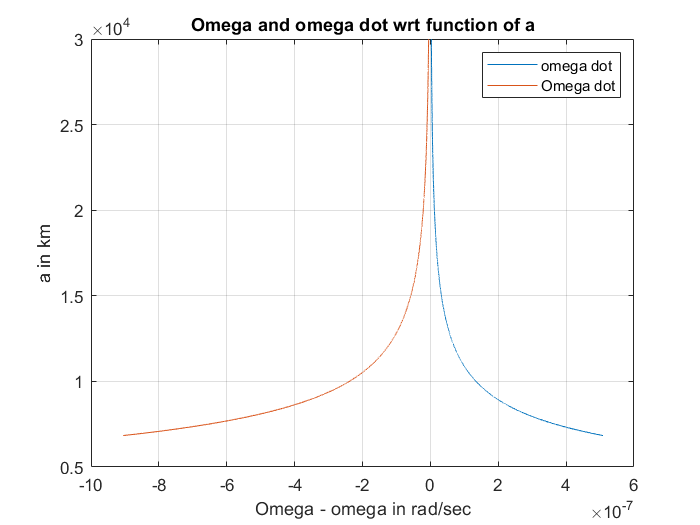

%function [r_b,v_b,zenit,Elevation,Azi,closeset,index_close,closest_v]=exercise_2_data(a,e,i,omega_1,omega_2)
clc;
clear all;
format long g;


%%provided data
c20=-0.00108263;
GM=398600.44;                             %unit is in km^3/s^2

%%unknown data
i=1.11784815920563;
e=0.00381415453739464;
a_e=6378;                          %semi-major of the earth value is in km
a=26500;                                 % semi major axis of the GPS
n = sqrt(GM/(a*a*a));
 T= 2*pi/(n);
 
%code for the exercise
%%task-1
d_a=0;
d_e=0;
d_omega=(3*n*c20*a_e*a_e)/(4*(((1-(e*e))*(1-(e*e)))*a*a))*(1-5*cos(i)*cos(i));
d_Omega=(3*n*c20*a_e*a_e)/(2*((1-(e*e))*(1-(e*e)))*a*a)*cos(i);
d_M=(3*n*c20*a_e*a_e)/(4*(((1-(e*e)))^(3/2)*a*a)*((3*cos(i)^(2))-1));

%%task-2
check=(d_M-n);
D_N= sqrt(GM/a^(3));

%%task-3

k=1;
for a=6838:1:30000
 sqrt_a=sqrt(a_e);
 i=deg2rad(55);
 e=0.01;
 a_vector=6838:1:30000;
 n = sqrt(GM/(a*a*a));
 %argument of perigee
d_omega_drei(k,:)=(3*n*c20*a_e^(2))/(4*(((1-(e*e))^(2))*a^(2)))*(1-5*cos(i)^(2));
%ascending node
d_Omega_drei(k,:)=(3*n*c20*a_e*a_e)/(2*((1-(e*e))*(1-(e*e)))*a*a)*cos(i);
 k=k+1;
end

%case-1
figure()
xlabel('omega dot and Omega dot');
ylabel('a');
plot(d_omega_drei,a_vector);
hold on
plot(d_Omega_drei,a_vector);
hold off 

grid on
legend({'Omega dot','omega dot'})
title('Omega and omega dot wrt function of a')
xlabel('Omega - omega in rad/sec')
ylabel('a in km')

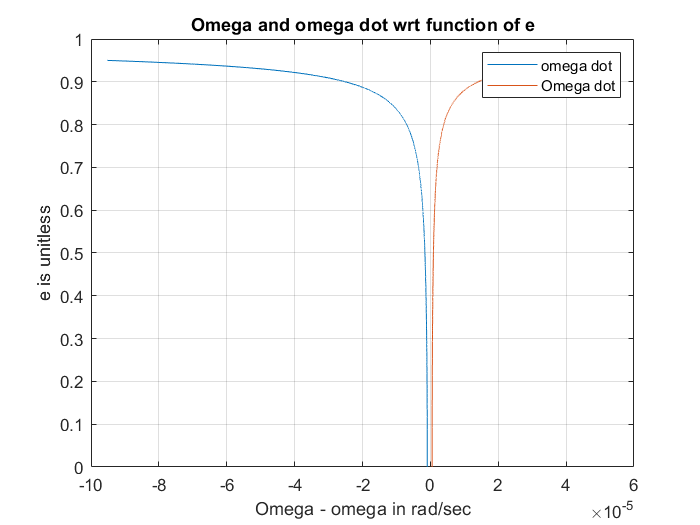




%task-3.2
 o=1;
 for e=0:0.0000410136856:0.95
     
     a=6838;
     e_vector=[0:0.0000410136856:0.95];
      i=deg2rad(55);
      n = sqrt(GM/(a*a*a));
   d_omega_drei(o,:)=(3*n*c20*a_e^(2))/(4*(((1-(e*e))^(2))*a^(2)))*(1-5*cos(i)^(2));
   d_Omega_drei(o,:)=(3*n*c20*a_e*a_e)/(2*((1-(e*e))*(1-(e*e)))*a*a)*cos(i);
  
   o=o+1;
 end

figure();

plot(d_Omega_drei,e_vector);
hold on
plot(d_omega_drei,e_vector);
hold off

grid on
legend({'omega dot','Omega dot'})
title('Omega and omega dot wrt function of e')
xlabel('Omega - omega in rad/sec')
ylabel('e is unitless')

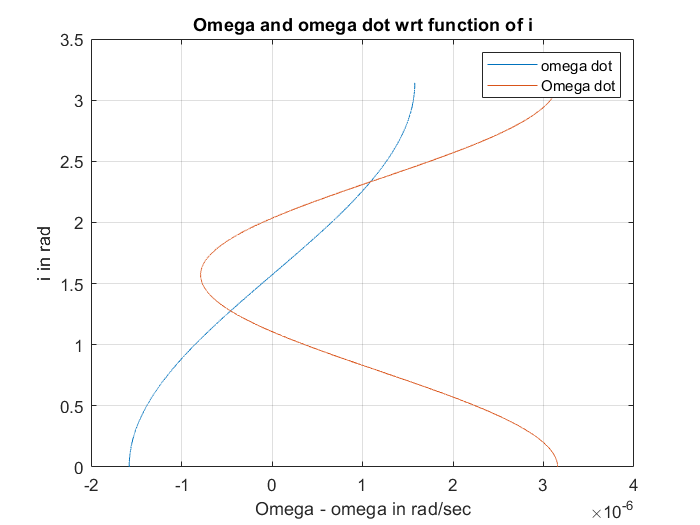



%task-3.3

  z=1;  
  for  i=deg2rad(0: 0.00777101411734231:180)
      i_vector=[0:0.0001356297825665842:3.14159265358979];
      e=0.01;
      a=6838;
      n = sqrt(GM/(a*a*a));
   d_omega_drei(z,:)=(3*n*c20*a_e^(2))/(4*(((1-(e*e))^(2))*a^(2)))*(1-5*cos(i)^(2));
   d_Omega_drei(z,:)=(3*n*c20*a_e*a_e)/(2*((1-(e*e))*(1-(e*e)))*a*a)*cos(i);
  
   z=z+1;
  end  
 figure();
plot(d_Omega_drei,i_vector);
hold on
plot(d_omega_drei,i_vector);
hold off

grid on
legend({'omega dot','Omega dot'})
title('Omega and omega dot wrt function of i')
xlabel('Omega - omega in rad/sec')
ylabel('i in rad')

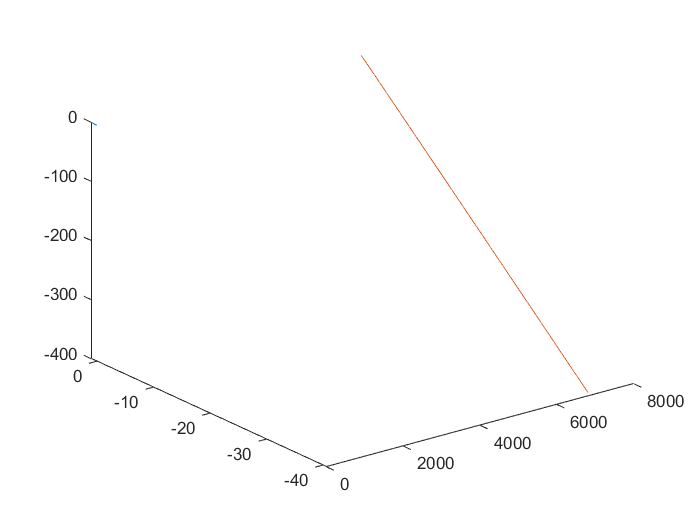



%%task-4


e=0.004;
eta=deg2rad(87);

  k=1;
    for i_1=0:10:2*T
                                  %mean anomly   %%3lines
    M0=0;
    t0=0;
    delta_t=i_1-t0;  
    M=M0+d_M*delta_t;
    E0=M;
    err=1;
    while(err>10^-12)
     
    E= M+e*sin(E0);
    err=abs(E-E0);                      % I want to understand this step
    E0=E;                               % eccentric anomly
    end
   v=2*atan(sqrt(1+e)*tan(E/2)/sqrt(1-e));    %atan2 is not working   % true anomly
   i=1.11784815920563;

            omega=0;   %longitude of the asceding node
            Omega=0;   %argument of periapsis
     
     omega_dot=(3*n*c20*a_e*a_e)/(4*(((1-(e*e))*(1-(e*e)))*a*a))*(1-5*cos(i)*cos(i));
     Omega_dot=(3*n*c20*a_e*a_e)/(2*((1-(e*e))*(1-(e*e)))*a*a)*cos(i);
     omega_perturbed=omega+omega_dot*delta_t;
     Omega_perturbed=Omega+Omega_dot*delta_t;
     
     
    r = a*(1-e*cos(E));                          %distance of the satellite

    r_b= [r*cos(v);r*sin(v);0]  ;                %position vector in the orbit system
    r_b1(k,:)=[a*(cos(E)-e);a*(sqrt(1-(e*e)))*sin(E);0];   %position vector in the orbit system


       v_b(k,:)=[-a*n*sin(E)*a/r,a*n*sqrt(1-(e*e))*cos(E)*a/r,0];    %velocity vector in the orbit system
  
    
     r_3_omega_1= [cos(-omega_perturbed) sin(-omega_perturbed) 0;-sin(-omega_perturbed) cos(-omega_perturbed) 0;0 0 1];
      r_3_omega_2= [cos(-Omega_perturbed) sin(-Omega_perturbed) 0;-sin(-Omega_perturbed) cos(-Omega_perturbed) 0;0 0 1];
     r_1=[1 0 0;0 cos(-eta) sin(-eta);0 -sin(-eta) cos(-eta)];
     r_i_perturbed= r_3_omega_1*r_1*r_3_omega_2*r_b;
     r_i1_perturbed(k,:)=transpose(r_i_perturbed);
    
        w_a=((2*pi)/86164);
       phi=w_a*(i-0);
       r_phi= [cos(phi) sin(phi) 0;-sin(phi) cos(phi) 0;0 0 1];
       r_e_perturbed=r_phi*r_i_perturbed;
       r_e1_perturbed(k,:)=r_phi*r_i_perturbed ;
       z_lat(k,:)= r_e1_perturbed(k,3);
       y_lat(k,:)=r_e1_perturbed(k,2);
       x_lat(k,:)=r_e1_perturbed(k,1);
      lat(k,:)= atan2((z_lat(k,:)),(sqrt((x_lat(k,:)*x_lat(k,:))+(y_lat(k,:)*y_lat(k,:)))));
      long(k,:)= atan2(y_lat(k,:),x_lat(k,:))  ;
         
   
   r_w=[4075.53022;931.78130;4801.61819];
   lat_w(k,:)=atan2(r_w(3,1),(sqrt(r_w(1,1)*r_w(1,1)+r_w(2,1)*r_w(2,1))));
   long_w(k,:)=atan2(r_w(2,1),r_w(1,1));
   A  = [-sin(lat_w(k,:))*cos(long_w(k,:)) -sin(long_w(k,:)) cos(lat_w(k,:))*cos(long_w(k,:));-sin(lat_w(k,:))*sin(long_w(k,:)) cos(long_w(k,:)) cos(lat_w(k,:))*sin(long_w(k,:));cos(lat_w(k,:)) 0 sin(lat_w(k,:))];
   r_top = transpose(A)*(r_e_perturbed-r_w);
   r_top1(k,:)=transpose(A)*(r_e_perturbed-r_w);

   close(k,:)=(r_e_perturbed-r_w);
   
   minimum_distance(k,:)=sqrt(close(k,1)^(2)+close(k,2)^(2)+close(k,3)^(2));
   closeset=min(minimum_distance);
   index_close=find(closeset==minimum_distance);
   closest_v=norm(v_b(index_close,:));
  
   S=sqrt(r_top(1,1).^2+r_top(2,1).^2+r_top(3,1).^2);
   S_1(k,:)=sqrt(r_top1(k,1).^2+r_top1(k,2).^2+r_top1(k,3).^2);
   
zenit(k,:)=acos(r_top(3,1)/S);
Elevation(k,:)=(pi/2) -zenit(k,:);
Azi(k,:)= atan2(-r_top1(k,2),r_top1(k,1));
 
   k=k+1;
    end

 



%task-5

    
   figure();
    plot3(r_1(:,1),r_1(:,2),r_1(:,3));
     hold on
     plot3(r_e1_perturbed(:,1),r_e1_perturbed(:,2),r_e1_perturbed(:,3));   
   hold off

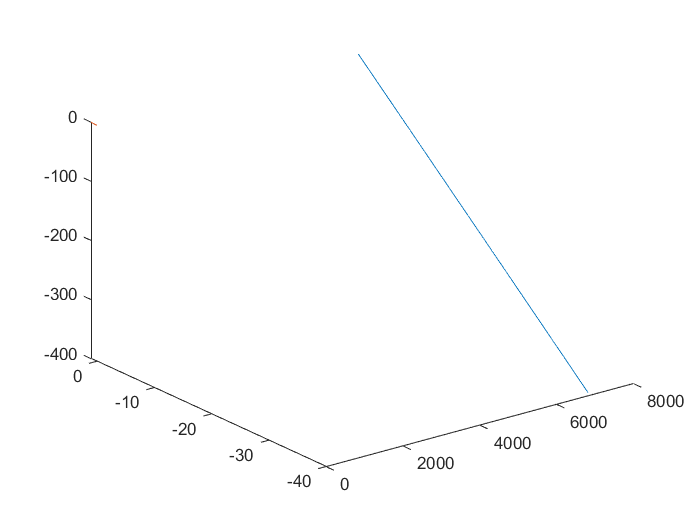


     figure();
    plot3(r_i1_perturbed(:,1),r_i1_perturbed(:,2),r_i1_perturbed(:,3));   
     hold on
     plot3(r_1(:,1),r_1(:,2),r_1(:,3));
     hold off

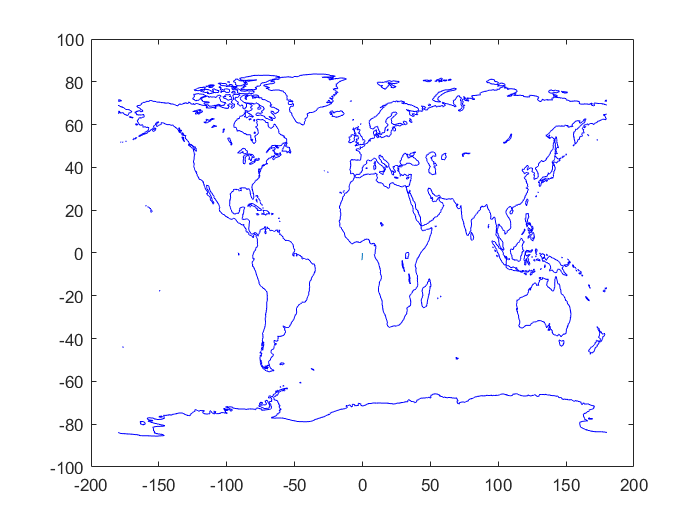

   
%task-5.2
 figure();
     plot(rad2deg(long),rad2deg(lat));
    hold on
   load coastlines
    geoshow(coastlat,coastlon);
    
    hold off

    
    figure();
    plot(rad2deg(long_pert),rad2deg(lat_pert));

Unrecognized function or variable 'long_pert'.

    hold on
   load coastlines
    geoshow(coastlat,coastlon);   
    hold off
   
earth_fixed_lat=lat_w_pert(1:1125)-lat_w;


figure();
plot(total_time_pert,earth_fixed_lat);


%task-5.3
 
figure();
plot(r_top1_perturbed);
hold on
plot(r_top1);
hold off



